clear; clc; close all;

%% Gain evaluation

 State Space Setup

Jxx = 0.002; Jyy = 0.002; Jzz = 0.002;
ts = 0.001;
tf = 15;
t = 0:ts:tf;

J = diag([Jxx Jyy Jzz]);

[A_nl,B_nl,x] = SymbolicMath(J);


Possible states

eulAngGrid = [ ...
    0 10 0;
    0 20 0;
    0 30 0];

roll = 0;
% pitch = union(-30:10:30,-5:5:5);
% yaw   = union(-30:10:30,-5:5:5);

pitch=0;
yaw=0;

[Roll, Pitch, Yaw] = ndgrid(roll,pitch,yaw);
rateGrid = arrayfun(@(r,p,y)[r p y], Roll, Pitch, Yaw, 'UniformOutput', false);


Constraints and params


veloMax = deg2rad(15);
dampingMin = 1e-4;
ctrlMax = 1.7e-3;
maxSet=7.5;
g = [70 0 0];


Sim setup

LB = [1e-4, 1e-4, 1e-4];
UB = [1e6, 1e6, 1e6];
G0 = [2.9679 .0001 8.4546e3];
lut={};
Gain = [];

optionsGa = optimoptions('ga', ...
    'InitialPopulationMatrix',Gain, ...
    'Display','iter', ...
    'PopulationSize',50, ...
    'MaxGenerations',10, ...
    'PlotFcn',@gaplotbestf);

optionsMinCon = optimoptions('fmincon', ...
    'Display','iter-detailed', ...
    'Algorithm','sqp', ...
    'MaxIterations',100, ...
    'StepTolerance',1e-8, ...
    'PlotFcn',{@optimplotfval,@optimplotconstrviolation});


 Loop

maxSet = 4

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    5.332320e+02     0.000e+00     1.000e+00     0.000e+00     0.000e+00  

Optimization completed: The final point is the initial point.
The first-order optimality measure, 0.000000e+00, is less than options.OptimalityTolerance =
1.000000e-06, and the maximum constraint violation, 0.000000e+00, is less than
options.ConstraintTolerance = 1.000000e-06.




Single objective optimization:
3 Variables
3 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1            835        726.69            0      0
    2           1358       226.045            0      0
    3           1881       226.045            0      1
Optimization finished: average change in the fitness value less than options.FunctionTolerance and constraint violation is less than options.ConstraintTolerance.


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    2.260446e+02     0.000e+00     1.000e+00     0.000e+00     0.000e+00  

Optimization completed: The final point is the initial point.
The first-order optimality measure, 0.000000e+00, is less than options.OptimalityTolerance =
1.000000e-06, and the maximum constraint violation, 0.000000e+00, is less than
options.ConstraintTolerance = 1.000000e-06.



Q =     0.0000         0         0         0         0         0
         0    2.0366         0         0         0         0
         0         0    2.0366         0         0         0
         0         0         0    0.0739         0         0
         0         0         0         0    0.0739         0
         0         0         0         0         0    0.0739


R = 1.0e+03 *

    5.5033         0         0
         0    5.5033         0
         0         0    5.5033


Ks =     0.0000    0.0000   -0.0017    0.0037    0.0000   -0.0003
   -0.0000    0.0192    0.0000   -0.0000    0.0072    0.0000
    0.0000   -0.0000    0.0192   -0.0003   -0.0000    0.0072


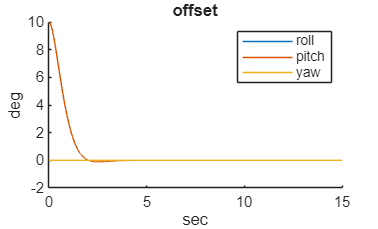

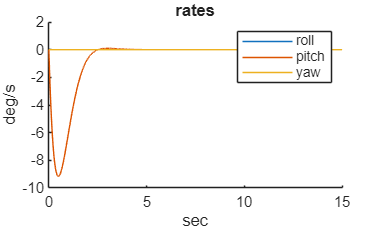

maxSet = 5

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    5.394323e+02     4.775e-01     1.000e+00     0.000e+00     0.000e+00  
you got a nan error in setTime
    1           9    1.237153e+03     0.000e+00     7.000e-01     4.898e+03     9.276e+07  
    2          13    1.237153e+03     0.000e+00     1.000e+00     1.697e-13     0.000e+00  

Optimization completed: The relative first-order optimality measure, 0.000000e+00,
is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.




Single objective optimization:
3 Variables
3 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
    1            573       843.349            0      0
    2           1096        738.92            0      0
    3           1619       619.127            0      0
    4           2142       618.295            0      0
Optimization finished: average change i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    6.182949e+02     0.000e+00     1.000e+00     0.000e+00     0.000e+00  

Optimization completed: The final point is the initial point.
The first-order optimality measure, 0.000000e+00, is less than options.OptimalityTolerance =
1.000000e-06, and the maximum constraint violation, 0.000000e+00, is less than
options.ConstraintTolerance = 1.000000e-06.



Q =     0.0000         0         0         0         0         0
         0    5.2618         0         0         0         0
         0         0    5.2618         0         0         0
         0         0         0    0.3751         0         0
         0         0         0         0    0.3751         0
         0         0         0         0         0    0.3751


R = 1.0e+05 *

    1.4790         0         0
         0    1.4790         0
         0         0    1.4790


Ks =     0.0000    0.0000   -0.0010    0.0017    0.0000   -0.0004
    0.0000    0.0060    0.0000   -0.0000    0.0038    0.0000
    0.0000   -0.0000    0.0059   -0.0004   -0.0000    0.0037


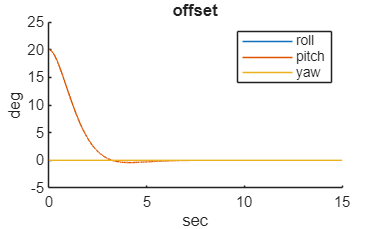

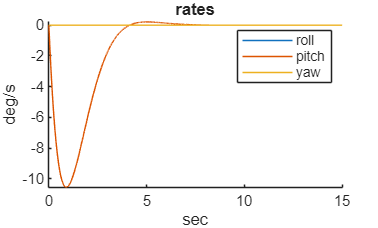

maxSet = 5

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    1.000188e+01     3.496e+00     1.000e+00     0.000e+00     0.000e+00  
you got a nan error in setTime
    1           9    2.519026e+02     8.261e-01     7.000e-01     2.093e+02     1.810e+04  
you got a nan error in setTime
you got a nan error in setTime
    2          19    1.250727e+03     7.382e-01     1.176e-01     2.103e+02     3.103e+04  
you got a nan error in setTime
    3          24    1.319100e+03     1.531e-02     7.000e-01     1.366e+03     3.911e+05  
    4          28    1.343521e+03     0.000e+00     1.000e+00     1.182e+01     1.965e-05  
    5          32    1.343521e+03     0.000e+00     1.000e+00     1.774e-06     0.000e+00  

Optimization completed: The relative first-order optimality measu


Single objective optimization:
3 Variables
3 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible
you got a nan error in setTime
you got a nan error in setTime

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a nan error in setTime
you got a n

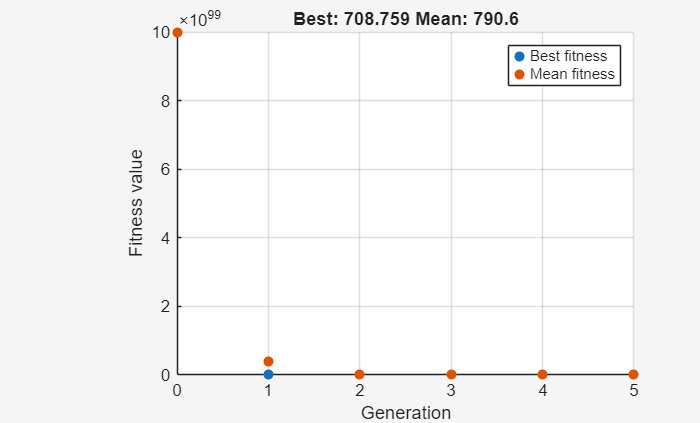

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    7.087587e+02     5.444e-04     1.000e+00     0.000e+00     0.000e+00  
    1          17    7.087587e+02     5.220e-04     4.035e-02     1.248e-03     1.156e-03  
    2          34    7.087587e+02     5.170e-04     9.689e-03     2.823e-04     1.156e-03  
    3          55    7.087587e+02     5.158e-04     2.326e-03     6.713e-05     1.156e-03  
    4          81    7.087587e+02     5.156e-04     3.910e-04     1.126e-05     1.156e-03  
    5         113    7.087587e+02     5.156e-04     4.600e-05     1.324e-06     1.156e-03  
    6         148    7.087587e+02     5.155e-04     1.578e-05     4.544e-07     1.156e-03  
    7         189    7.087587e+02     5.155e-04     1.856e-06     5.342e-08     2.990e+07  
    8         293    7.087587e+02     5.155e-04     8.812e-09     7.084e-07     2.

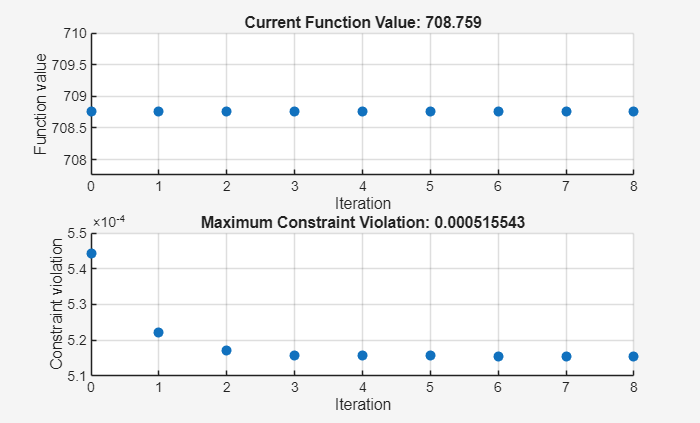

Q =     0.0000         0         0         0         0         0
         0   10.7628         0         0         0         0
         0         0   10.7628         0         0         0
         0         0         0    0.8762         0         0
         0         0         0         0    0.8762         0
         0         0         0         0         0    0.8762


R = 1.0e+05 *

    3.7196         0         0
         0    3.7196         0
         0         0    3.7196


Ks =     0.0000    0.0000   -0.0014    0.0017    0.0000   -0.0005
   -0.0000    0.0054    0.0000   -0.0000    0.0036    0.0000
    0.0000   -0.0000    0.0052   -0.0005   -0.0000    0.0035


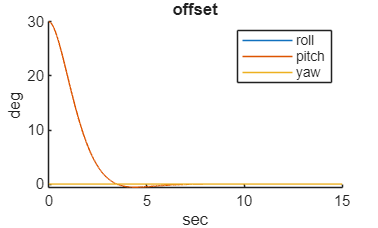

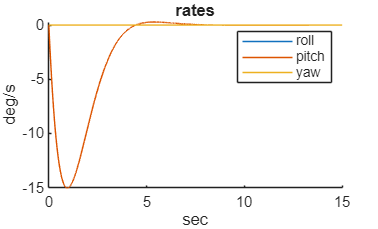

for m = 1:height(eulAngGrid)

    if m==1
        maxSet=4
    else 
        maxSet=5
    end
    if m==3
        G0=[1 1e-4 .9832];
    end
    eulAng = eulAngGrid(m,:);
    %omega = rateGrid{1,n,o};
    omega=[0 0 0];

    x0 = MakeX(eulAng,omega);
    Gain=G0;
    A = double(subs(A_nl,x,x0));
    B = double(subs(B_nl,x,x0));
    C = eye(6);

    cost = @(G) gainCost(G,A,B,C,J,x0,ts,g,t);
    constraint = @(G) gainConstraint(G,A,B,C,x0,veloMax,maxSet,ctrlMax,t);


while true
    [Gain,~,~,~] = fmincon(cost,Gain,[],[],[],[],LB,UB,constraint,optionsMinCon);
    [Gain,~,~,~] = ga(cost,3,[],[],[],[],LB,UB,constraint,optionsGa);
    [Gain,~,~,~] = fmincon(cost,Gain,[],[],[],[],LB,UB,constraint,optionsMinCon);
  
    if cost(Gain)<1e10
        break
    end 
end


    Q = diag([eps, Gain(1), Gain(1), Gain(2), Gain(2), Gain(2)])
    R = Gain(3)*eye(3)

    [Ks,~,~] = lqr(A,B,Q,R);
    Ks
    lut{m}=Ks;

    sysTemp = ss(A-B*Ks,B,C,[]);
    xTemp = initial(sysTemp,x0,t);
    uTemp = -xTemp*Ks';
    maxCtrl = max(vecnorm(uTemp,2,2))*1e3;
            
    q0Temp=(ones(size(xTemp,1),1)-xTemp(:,1).^2-xTemp(:,2).^2-xTemp(:,3).^2).^(1/2);
    quatTemp=[q0Temp,xTemp(:,1:3)];
    eulTemp=rad2deg(quat2eul(quatTemp));

    figure; hold on
    plot(t,eulTemp(:,1:3))
    legend('roll','pitch','yaw')
    ylabel('deg')
    xlabel('sec')
    title('offset')
    hold off

    figure; hold on
    plot(t,rad2deg(xTemp(:,4:6)))
    legend('roll','pitch','yaw')
    ylabel('deg/s')
    xlabel('sec')
    title('rates')
    hold off
end

        save('lqrLUT.mat','lut')
        disp('lut saved')

lut saved


Cost Function

function [cost,setTime,peakJerk,incrCtrl,Q,R] = gainCost(G,A,B,C,J,x0,ts,g,t)

Q = diag([eps, G(1), G(1), G(2), G(2), G(2)]);
R = G(3)*eye(3);

setTime = nan;
peakJerk = nan;
incrCtrl = nan;


for k=1:3
    if G(k)>10^7
        cost = 1e20;
        disp('failed Gain to big')
        return
    end
end

[K,~,~] = lqr(A,B,Q,R);

Acl = A-B*K;
sys = ss(Acl,B,C,[]);
sys = c2d(sys,ts);

x = initial(sys,x0,t);
u = -x*K';

alpha = (u./diag(J)');
[~,jerk] = gradient(alpha,ts);
peakJerk = max(vecnorm(jerk,1));

if abs(x(end,2))<(x0(2)*.02)
    idxSet=find(abs(x(:,2)) > max(abs(x(:,2)))*0.02,1,'last');
    setTime=t(idxSet);

end

    incrCtrl=sum(trapz(t,jerk.*(jerk>0)));
    xPeak=cell(1,3);
    tPeak=cell(1,3);
    damping=zeros(1,3);
        for j=1:3
            peak_loc(1,j)=x(2,j)<x(1,j);
            for i=2:length(t)-1
                peak_loc(i,j)=x(i+1,j)<x(i,j) && x(i-1,j)<x(i,j);
            end
            idxPeak=find(peak_loc(:,j)==1);
            xPeak{j}=x(idxPeak,j);
            tPeak{j}=t(idxPeak)';  
            if length(xPeak{j})>1
                expFit=fit(tPeak{j},xPeak{j},"exp1");
                damping(j)=expFit.b;
            end 
        end  

     dampingNorm=norm(damping);
            
     if isnan(setTime)
         cost=1e100;
         disp("you got a nan error in setTime")
         return
     end
     if isnan(incrCtrl)
         cost=1e3;
         disp("you got a nan error in incrCtrl")
         return
     end
cost = g(1)*(setTime^2) + g(2)*incrCtrl+g(3)*dampingNorm;
end


Constraint Function

function [c,ceq] = gainConstraint(G,A,B,C,x0,veloMax,maxSet,ctrlMax,t)

Q = diag([eps, G(1), G(1), G(2), G(2), G(2)]);
R = G(3)*eye(3);
ceq = [];
setTime=nan;

if any(G<=0)
    c = ones(3,1)*1e100;
    disp("Q or R not pos def")
    return
end

for k=1:3
    if G(k)>10^11
        c = ones(3,1)*1e100;
        disp('failed gain to big')
        return
    end
end

[K,~,~] = lqr(A,B,Q,R);
Acl = A-B*K;

sys = ss(Acl,B,C,[]);
x = initial(sys,x0,t);
u = -x*K';

if abs(x(end,2))<(x0(2)*.02)
    idxSet=find(abs(x(:,2)) > max(abs(x(:,2)))*0.02,1,'last');
    setTime=t(idxSet);
end

if isnan(setTime)
    setTime=100;
end


absVelo = abs(x(:,4:6));
peakVelo = max(vecnorm(absVelo,2,2));
peakCtrl = max(vecnorm(u,2,2));

c1 =setTime^2-maxSet^2;
c2 = peakVelo - veloMax;
c3 = (peakCtrl - ctrlMax)/peakCtrl;

c = [c1 c2 c3];
end


State space setup

function [x_lin] = MakeX(eulAngdeg,angRates)

eulAng = deg2rad(eulAngdeg);
q = eul2quat(eulAng);

q_lin = q(2:4)';
w_lin = deg2rad(angRates)';

x_lin = [q_lin; w_lin];
end

%% Symbolic math
function [A_nl,B_nl,x] = SymbolicMath(J)

syms q1 q2 q3 w1 w2 w3 u1 u2 u3
J_inv = J^-1;

q = [q1;q2;q3];
w = [w1;w2;w3];
u = [u1;u2;u3];
x = [q; w];

q0 = sqrt(1-q1^2-q2^2-q3^2);

Omega = [ q0 -q3  q2;
          q3  q0 -q1;
         -q2  q1  q0];

f = [0.5*Omega*w;
     J_inv*u];

for idx1 = 1:size(f,1)
    for idx2 = 1:size(x,1)
        A_nl(idx1,idx2) = diff(f(idx1),x(idx2));
    end
    for idx3 = 1:size(u,1)
        B_nl(idx1,idx3) = diff(f(idx1),u(idx3));
    end
end
end
